**Create a Demonstration Lane System**

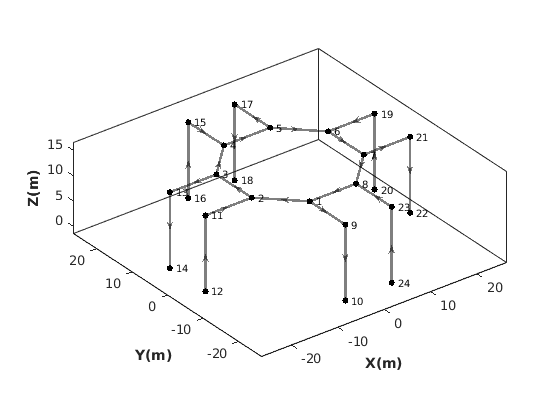

lbsd = LBSD.genSampleLanes(10, 15);

plot(lbsd);

**Create A Couple UAS**

num_uas = 5

num_uas = 5

uas_arr(num_uas) = UAS();
% The default ID of the uas class is a random
% uuid, so rename the ids to ints to make it
% easier to track. Also, give each uas a reference
% to the lbsd.
for i = 1:num_uas
    uas_arr(i).id = string(i);
    uas_arr(i).lbsd = lbsd;
end
uas_arr(1)

ans =   UAS with properties:

                     id: "1"
                    gps: [1×1 GPS]
                     kb: []
                   lbsd: [1×1 LBSD]
             climb_rate: 1
          nominal_speed: 1
           set_point_hz: 1
                res_ids: []
    telemetry_listeners: []
                   traj: []
     failed_to_schedule: 0
            traj_step_i: 0
                    r_s: 0
                  toa_s: []
                    t_s: 0
                 active: 0
                    h_d: 10
                   flex: 0
                      h: []
              exec_traj: []
            exec_orient: []
               exec_vel: []
             exec_accel: []
           exec_ang_vel: []


[traj, lane_ids, vert_ids, toa_s] = uas_arr(1).createTrajectory([-20,-20],[20,20]);

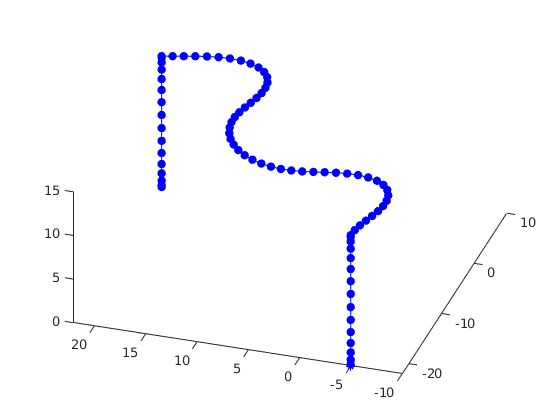

h = lbsd.plot()